# Generating Full Allocation PDSCH Resource Grid (Single Antenna)

In this exercise you will generate a single antenna full allocation PDSCH resource grid.

Set up a carrier configuration object with the default parameters. (*Name it "carrier".*)

carrier = nrCarrierConfig

carrier =   nrCarrierConfig with properties:

              NCellID: 1
    SubcarrierSpacing: 15
         CyclicPrefix: 'normal'
            NSizeGrid: 52
           NStartGrid: 0
                NSlot: 0
               NFrame: 0

   Read-only properties:
       SymbolsPerSlot: 14
     SlotsPerSubframe: 1
        SlotsPerFrame: 10


Set up a PDSCH configuration object named "pdsch". We will use 16QAM modulation and full band allocation. (*Set PRBSet property range using carrier.NSizeGrid. Resource block indices start from 0.*) Other time allocation parameters and DM-RS settings can be specified in this object.

pdsch = nrPDSCHConfig;
pdsch.Modulation = "16QAM";
pdsch.PRBSet = 0:carrier.NSizeGrid-1;     % assume full band allocation

Display the PDSCH and PDSCH DM-RS parameters. (*Just call the variable and property of that variable using dot notation.*)

pdsch

pdsch =   nrPDSCHConfig with properties:

                NSizeBWP: []
               NStartBWP: []
             ReservedPRB: {[1×1 nrPDSCHReservedConfig]}
              ReservedRE: []
              Modulation: '16QAM'
               NumLayers: 1
             MappingType: 'A'
        SymbolAllocation: [0 14]
                  PRBSet: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51]
    VRBToPRBInterleaving: 0
           VRBBundleSize: 2
                     NID: []
                    RNTI: 1
                    DMRS: [1×1 nrPDSCHDMRSConfig]
              EnablePTRS: 0
                    PTRS: [1×1 nrPDSCHPTRSConfig]

   Read-only properties:
            NumCodewords: 1


pdsch.DMRS

ans =   nrPDSCHDMRSConfig with properties:

      DMRSConfigurationType: 1
         DMRSReferencePoint: 'CRB0'
          DMRSTypeAPosition: 2
     DMRSAdditionalPosition: 0
                 DMRSLength: 1
            CustomSymbolSet: []
                DMRSPortSet: []
                   NIDNSCID: []
                      NSCID: 0
    NumCDMGroupsWithoutData: 2

   Read-only properties:
                  CDMGroups: 0
                DeltaShifts: 0
           FrequencyWeights: [2×1 double]
                TimeWeights: [2×1 double]
    DMRSSubcarrierLocations: [6×1 double]
                 CDMLengths: [1 1]


Generate an empty resource grid. (*Name the grid "pdschGrid".* *Remember to pass the carrier as an input argument.*) This grid represents a slot.

pdschGrid = nrResourceGrid(carrier);

Generate indices to map the PDSCH to the grid. (*Remember to look at the doc for proper calling syntax. Name the output parameters "pdschIndices" and "pdschInfo".*)

[pdschIndices,pdschInfo] = nrPDSCHIndices(carrier,pdsch);

Generate random PDSCH bits and map to PDSCH symbols. For simplicity, this example does not include the DL-SCH modeling. 

pdschBits = randi([0 1],pdschInfo.G,1);

Generate PDSCH symbols (*Name them "pdschSymbols".*)

pdschSymbols = nrPDSCH(carrier,pdsch,pdschBits);

Map the PDSCH symbols to the grid and display the resource grid. (*MATLAB uses linear indexing to map the symbols to the grid.*) Note the gap left for the DM-RS.

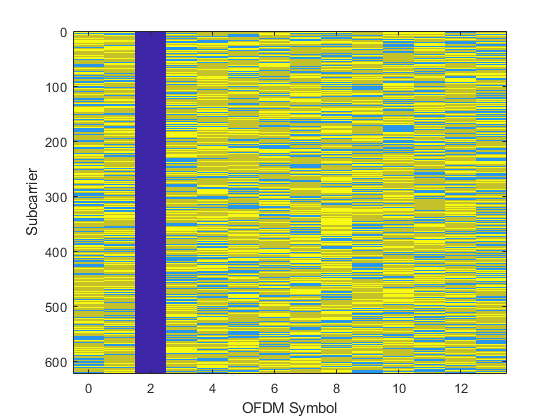

pdschGrid(pdschIndices) = pdschSymbols;
imagesc([0 carrier.SymbolsPerSlot-1],[0 carrier.NSizeGrid*12-1],abs(pdschGrid));xlabel('OFDM Symbol');ylabel('Subcarrier')

Generate DM-RS symbols and indices. (*Name them "dmrsSymbols" and "dmrsIndices", respectively.*)

dmrsSymbols = nrPDSCHDMRS(carrier,pdsch);
dmrsIndices = nrPDSCHDMRSIndices(carrier,pdsch);

Map the DM-RS symbols to the grid. (*Use linear indexing to do the mapping.*)

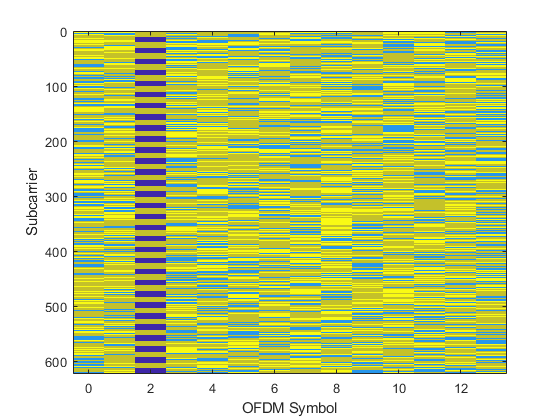

pdschGrid(dmrsIndices) = dmrsSymbols;
imagesc([0 carrier.SymbolsPerSlot-1],[0 carrier.NSizeGrid*12-1],abs(pdschGrid));xlabel('OFDM Symbol');ylabel('Subcarrier')

Perform OFDM modulation of the resource grid. (*Name the two modulation output parameters "txWaveform" and "waveformInfo", respectively.*)

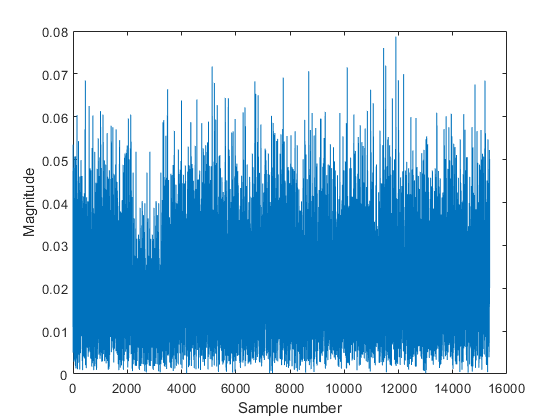

[txWaveform,waveformInfo] = nrOFDMModulate(carrier,pdschGrid);
plot(abs(txWaveform));xlabel('Sample number');ylabel('Magnitude')

The `waveformInfo` ouptput contains information about the time domain waveform, such as the sampling rate.

waveformInfo

waveformInfo = struct with fields:
                   Nfft: 1024
             SampleRate: 15360000
    CyclicPrefixLengths: [80 72 72 72 72 72 72 80 72 72 72 72 72 72]
          SymbolLengths: [1104 1096 1096 1096 1096 1096 1096 1104 1096 1096 1096 1096 1096 1096]
              Windowing: 36
           SymbolPhases: [0 0 0 0 0 0 0 0 0 0 0 0 0 0]
         SymbolsPerSlot: 14
       SlotsPerSubframe: 1
          SlotsPerFrame: 10
